% n=10;
% mypath = rand(n,2);
% m = cumsum(mypath);
% mout = m./m(end,:);    
% load("X1.mat");
% load("Y1.mat");
% load("curve_one.mat");
% % disp(curve_one)
% % plot(X1,Y1)


### **Breakdown of 9X21 Grid**

**Three vertical sections**: subject, verb, object

**Three horizontal sections**: prefix, affix, suffix

### Variables to keep at all points 

- Current X, Y, pressure and time ***Done***

- x and y position vectors (1-9 and 1-21) ***Done***

- pressure vector (1-3) ***Done***

- direction of movement (1-8) 

**Functions needed**

- Randomly choose origin in the prefix column 

-     Choose starting x(1-3)

-     Choose starting y(1-3)

- Randomly choose functions

- Randomly change direction

-     Directions allowed to move (N(1) to NW(8))    

- Randomly change pressure

- Randomly change speed 

**Move n= 1, 2, 3 or 4 units**      

### Subject (1,1 to 9,7)

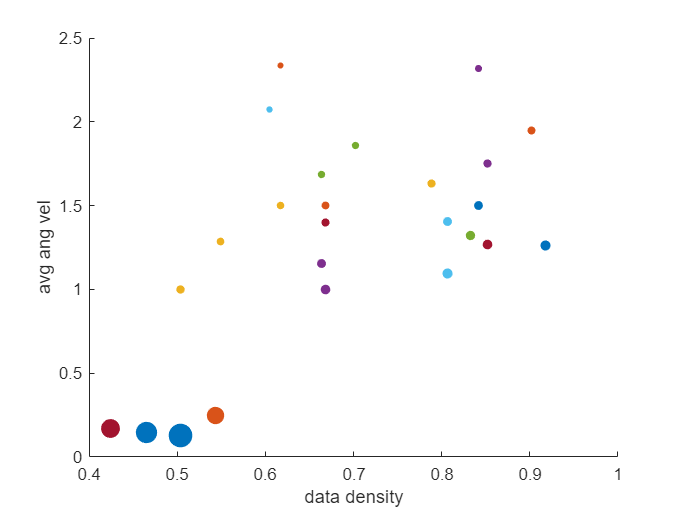

ratio =   Nonlinear OptimizationExpression

    calculateGeneratorPerformance(n, k, Xop1, Xop2, Xop3, Yop1, Yop2, Yop3, pp1, pp2, pp3)


% Hyperparameters
% k - scale of range of probabilities that forward direction can take
% n - skewness of distribution of direction probabilities
% origin_probabs - probability weights for choosing origin 
% propogation_probabs - probability weights for propogation 1 2 or 3 units at step
% 


% x0=[0.9 0.5 0.6 0.25 0.15 0.25 0.5 0.25 0.4 0.4 0.2];
% ratio = calculateGeneratorPerformance(x0);
% options = optimset('PlotFcns',@optimplotfval);
% x=fminsearch(@calculateGeneratorPerformance,x0,options)
% 
% z=calculateGeneratorPerformance(0.0694,0.0578,0.0175,0.0198,0.9627,0.0286,0.0235,0.9480,0.9945,0.0044,0.0011)

n=optimvar("n","LowerBound",0,"UpperBound",1);
k=optimvar("k","LowerBound",0,"UpperBound",1);
Xop1=optimvar("Xop1","LowerBound",0.001,"UpperBound",1);
Xop2=optimvar("Xop2","LowerBound",0.001,"UpperBound",1);
Xop3=optimvar("Xop3","LowerBound",0.001,"UpperBound",1);
Yop1=optimvar("Yop1","LowerBound",0.001,"UpperBound",1);
Yop2=optimvar("Yop2","LowerBound",0.001,"UpperBound",1);
Yop3=optimvar("Yop3","LowerBound",0.001,"UpperBound",1);
pp1=optimvar("pp1","LowerBound",0.001,"UpperBound",1);
pp2=optimvar("pp2","LowerBound",0.001,"UpperBound",1);
pp3=optimvar("pp3","LowerBound",0.001,"UpperBound",1);
ratio=fcn2optimexpr(@calculateGeneratorPerformance,n,k,Xop1,Xop2,Xop3,Yop1,Yop2,Yop3,pp1,pp2,pp3)

prob = optimproblem();
prob.Objective.ratio=ratio;
prob.ObjectiveSense = "minimize";
prob.Objective.len=n+k;
prob.ObjectiveSense = "minimize";
prob.Constraints.cons1=Xop1+Xop2+Xop3==1;
prob.Constraints.cons2=Yop1+Yop2+Yop3==1;
prob.Constraints.cons3=pp1+pp2+pp3==1;
prob.Constraints.cons4=Xop1*Xop2*Xop3>=0.03;
prob.Constraints.cons5=Yop1*Yop2*Yop3>=0.03;
prob.Constraints.cons6=pp1*pp2*pp3>=0.03;
show(prob);


  OptimizationProblem : 

	Solve for:
       Xop1, Xop2, Xop3, Yop1, Yop2,
     Yop3, k, n, pp1, pp2, pp3

	minimize ratio:
       calculateGeneratorPerformance(n,
       k, Xop1, Xop2, Xop3, Yop1,
     Yop2, Yop3, pp1, pp2, pp3)

	minimize len:
       n + k



	subject to cons1:
       Xop1 + Xop2 + Xop3 == 1

	subject to cons2:
       Yop1 + Yop2 + Yop3 == 1

	subject to cons3:
       pp1 + pp2 + pp3 == 1

	subject to cons4:
       ((Xop1 .* Xop2) .* Xop3) >=
       0.03

	subject to cons5:
       ((Yop1 .* Yop2) .* Yop3) >=
       0.03

	subject to cons6:
       ((pp1 .* pp2) .* pp3) >= 0.03

	variable bounds:
       0.001 <= Xop1 <= 1

       0.001 <= Xop2 <= 1

       0.001 <= Xop3 <= 1

       0.001 <= Yop1 <= 1

       0.001 <= Yop2 

% options = optimoptions(@ga,...
%     'PlotFcn',{@gaplotbestf,@gaplotmaxconstr},...
%     'PopulationSize',50,...
%     'MaxGenerations',20,...
%     'Display','iter');
% [sol,fval] = solve(prob,"Solver","ga","Options",options)

% 
% [sol,fval] = solve(prob,"Solver","gamultiobj","Options",options)

% n=0.0694;
% k=0.0578;
% Xop1=0.0175;
% Xop2=0.0198;
% Xop3=0.9627;
% Yop1=0.0286;
% Yop2=0.0235;
% Yop3=0.9480;
% pp1=0.9945;
% pp2=0.0044;
% pp3=0.0011;
n=0.3552;
k=0.2612;
Xop1=0.2446;
Xop2=0.3052;
Xop3=0.4502;
Yop1=0.3272;
Yop2=0.3304;
Yop3=0.3424;
pp1=0.4965;
pp2=0.2729;
pp3=0.2306;

z=calculateGeneratorPerformance(n,k,Xop1,Xop2,Xop3,Yop1,Yop2,Yop3,pp1,pp2,pp3)
switch_pressure_probabilities=[];
switch_speed_probabilites=[];
X_origin_probabs = [Xop1 Xop2 Xop3];
Y_origin_probabs = [Yop1 Yop2 Yop3];
propagation_probabilities = [pp1 pp2 pp3];
[X1_positions, Y1_positions, dir_sequence1]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
length_1 = length(dir_sequence1)
data_density1=data_density_rel(X1_positions,Y1_positions)
average_angular_vel1 = angular_vel_avg(dir_sequence1)
ratio1= data_density1/average_angular_vel1

[X2_positions, Y2_positions, dir_sequence2]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
length_2 = length(dir_sequence2)
data_density2=data_density_rel(X2_positions,Y2_positions)
average_angular_vel2 = angular_vel_avg(dir_sequence2)
ratio2= data_density2/average_angular_vel2

gestalt_distance = gestaltDistance(char(strjoin(string(dir_sequence1))),char(strjoin(string(dir_sequence1))))
frechet_distance = frechet(X1_positions',Y1_positions',X2_positions',Y2_positions')

%Plot stroke
hold off
plot(X1_positions,Y1_positions,'LineWidth',3)
hold on 
plot(X2_positions,Y2_positions,'LineWidth',3)
xlim([1 9])
ylim([1 21])
set(gca, 'YDir','reverse')
grid on
pbaspect([1 1 1])
daspect([1 1 1])
hold off


% function f=calculateGeneratorPerformance(x)
% n=x(1);
% k=x(2);
% Xop1=x(3);
% Xop2=x(4);
% Xop3=x(5);
% Yop1=x(6);
% Yop2=x(7);
% Yop3=x(8);
% pp1=x(9);
% pp2=x(10);
% pp3=x(11);



function f=calculateGeneratorPerformance(n,k,Xop1,Xop2,Xop3,Yop1,Yop2,Yop3,pp1,pp2,pp3)
X_origin_probabs = [Xop1 Xop2 Xop3];
Y_origin_probabs = [Yop1 Yop2 Yop3];
propagation_probabilities = [pp1 pp2 pp3];
switch_pressure_probabilities = [];
switch_speed_probabilites = [];
generator_avg_ang_vel=[];
generator_avg_data_density=[];
generator_ratio=[];
for iter=1:25
    [X_positions, Y_positions, dir_sequence] = generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
    data_density=data_density_rel(X_positions,Y_positions);
    average_angular_vel = angular_vel_avg(dir_sequence);
    ratio=1;
    if average_angular_vel ~=0
        ratio = data_density/average_angular_vel;
    end
    
    generator_avg_ang_vel(end+1)=average_angular_vel;
    generator_avg_data_density(end+1)=data_density;
    generator_ratio(end+1)=ratio;
    scatter(data_density,average_angular_vel,50*ratio,"filled")
    xlabel('data density')
    ylabel('avg ang vel')
    hold on
end
    hold off
    gross_avg_data_density=sum(generator_avg_data_density)/20;
    gross_avg_ang_vel=sum(generator_avg_ang_vel)/20;
    gross_ratio=sum(generator_ratio)/20;
    f=gross_ratio;
end



function [X_positions, Y_positions, dir_sequence]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites )

s = RandStream('mlfg6331_64','Seed','shuffle');
X_positions = [];
Y_positions = [];
pressure_variation = [];
pressure_current = 0;
time_frame = 0;

% Choose origin
% Choose starting x and y
X_origin = randsample(s,1:3,1,true,X_origin_probabs);
Y_origin = randsample(s,[1 4 7],1,true,Y_origin_probabs);
time_frame = 1;
X_positions(end+1)=X_origin;
Y_positions(end+1)=Y_origin;

pressure_current = 1;
pressure_variation(end+1)=pressure_current;
prop_dir = 0;
dir_sequence = [];
m=1; reached_edge=0; hitting_edge=0;
while m<=15 && reached_edge==0 && hitting_edge==0
    m=m+1;
    % Randomly choose propogation length
    % Propogate 1-4 units
    dir = [1 2 3 4 5 6 7 8];
    prop_len = randsample(s,1:3,1,true,propagation_probabilities);
    
    % Calculate possible directions
    % -Cannot cross left edge
    if X_positions(end)-prop_len<=0
        dir(dir==6 | dir==7 | dir==8) = [];
    end
    % -Cannot cross top edge
    if Y_positions(end)-prop_len<=0
        dir(dir==8 | dir==1 | dir==2) = [];
    end
    % -Cannot cross right edge
    if X_positions(end)+prop_len>=10
        dir(dir==2 | dir==3 | dir==4) = [];
%         disp("hitting right edge, breaking")
           hitting_edge=1;
    end
    % -Cannot cross bottom edge
    if Y_positions(end)+prop_len>=8
        dir(dir==6 | dir==5 | dir==4) = [];
    end
    
    % Select direction randomly
    last_dir = prop_dir;
    dir_len = length(dir);
    sz = size(dir);
    dir_probabs = ones(sz)*(1/dir_len);
    prop_dir = randsample(s,dir,1,true,dir_probabs_gen(dir,k,n));
    
    iter = 1;
    % Propogate
    while iter<=prop_len && reached_edge==0
        iter = iter+1;
        time_frame = time_frame + 1;
        if prop_dir<5 && prop_dir>1
            X_positions(end+1)=X_positions(end)+1;
        end
        if prop_dir>5 && prop_dir<9
            X_positions(end+1)=X_positions(end)-1;
        end
        if prop_dir<7 && prop_dir>3
            Y_positions(end+1)=Y_positions(end)+1;
        end
        if prop_dir<3 || prop_dir>7
            Y_positions(end+1)=Y_positions(end)-1;
        end
        if prop_dir==1 || prop_dir==5
            X_positions(end+1)=X_positions(end);
        end
        if prop_dir==7 || prop_dir==3
            Y_positions(end+1)=Y_positions(end);
        end
        dir_sequence(end+1)=prop_dir;
        pressure_variation(end+1)=pressure_current;
        if X_positions(end)==9
%             disp("reached X=9 breaking")
            reached_edge=1;
        end
    end
end
end


% Randomly Choose dynamic variations                      Probabilities
% 0 : no change                                               0.7
% 1 : change pressure randomly 1 step up or down              0.2
% 2 : change speed 1 tempo randomly                           0.1


function y = data_density_rel(X_positions,Y_positions)
    gesture = zeros(9,7);
    for n=1:length(X_positions)
        gesture(Y_positions(n),X_positions(n))=1;
    end
    y = entropy(mat2gray(gesture)) ;
end

function y = dir_probabs_gen(dir,k,n)
% k=scale for range of probability for 3 between 2/7 and 1 (0-1)
% m=slope of distribution
m=rand*(1-n)+n;
min_probab_3 = (k*3 + 2)/7;
probab_3 = rand*(1-min_probab_3)+min_probab_3;
probabs=[];
m = m*min_probab_3/4;
% index= [1 2 3 4 5 6 7 8]
for i=1:length(dir)
    if dir(i)==3
        probabs(end+1)=probab_3;
    end
    if dir(i)==2 || dir(i)==4
        probabs(end+1)=probab_3-m;
    end
    if dir(i)==1 || dir(i)==5
        probabs(end+1)=probab_3-2*m;
    end
    if dir(i)==8 || dir(i)==6
        probabs(end+1)=probab_3-3*m;
    end
    if dir(i)==7
        probabs(end+1)=probab_3-4*m;
    end
end
y=probabs;
end

function y = gestaltDistance(X,Y)
total_len = length(X)+length(Y);
endloop = 0;
K=0;
while endloop==0
   [substr] = commonsubstring(char(X),char(Y));
   if isempty(substr)
       endloop=1;
   end
   if size(substr,1)>1
        for i=1:size(substr,1)
            K=K+length(substr(i,:));
            X=erase(X,substr(i,:));
            Y=erase(Y,substr(i,:));
        end
   else
       K=K+length(substr);
       X=erase(X,substr);
       Y=erase(Y,substr);
   end
end
y=(2*K)/(total_len);
end


function y = angular_vel_avg(X)
% Angular Velocity: rate of change of angle
% final angle - initial angle
% increase: (final - initial) * 45'
% decrease: abs(final - initial)* 45'
% ((b - a) + len) % len), where a is the "from" index, b is the "to" index, and len is the length of the array
    dirs = [1 2 3 4 5 6 7 8];
    av=0;
    for i=2:length(X)
        b=find(dirs==X(i));
        a=find(dirs==X(i-1));
        diff= mod(((b - a) + 8), 8);
        if diff<0
            disp("negative diff")
        end
        av=av+diff;
    end
    y=av/length(X);
end